# ENGE 1414 MATLAB Guided Notes

Instructor: Wallwey

Semester/Class: Fall 2023 / Class 5.2

clear all % clear all previous variables
close all % closes all previously open figures
clc % clear the command window

## Example 1: Scatter Plot 

Practice with the *plot* function 

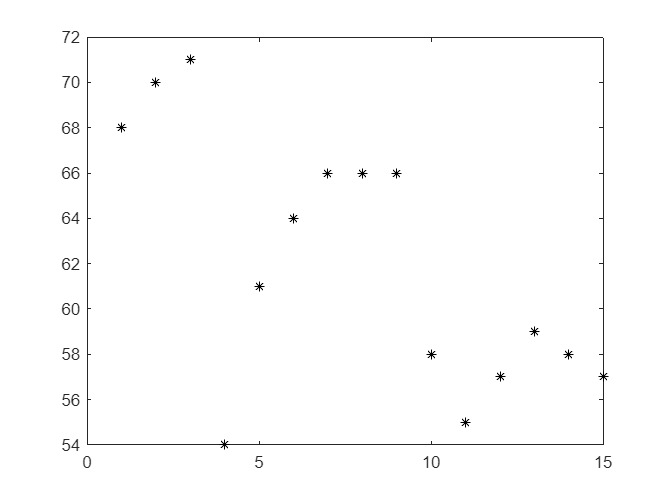

% data
days = [1:1:15];
high_temps = [68 70 71 54 61 64 66 66 66 58 55 57 59 58 57];

figure % Opens a new figure for this plot to go on

% now plot this data below
plot(days,high_temps,"*k")

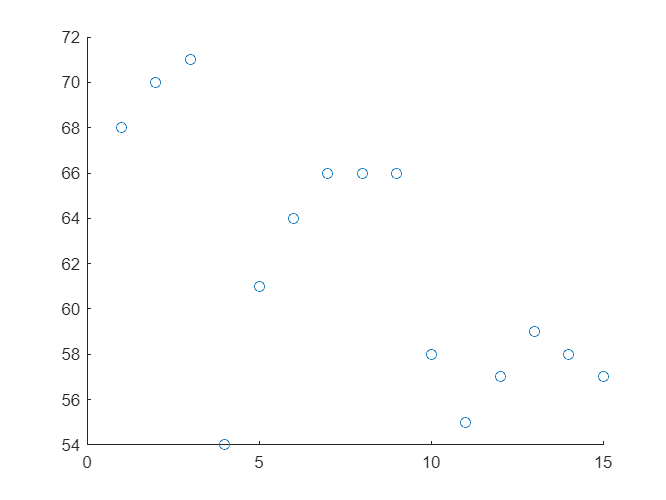

title('High temps over the last 15 days.')
xlabel('Day')
ylabel('Temperature (F)')
scatter(days,high_temps)

## Example 2: Multiple Plots

% new data to work with
days = [1:1:15];
low_temps = [43 45 41 34 36 41 45 47 46 37 37 39 40 40 36];

Practice with the *hold on* function

figure % Opens a new figure for this practice plot to go on

% practice code goes here

Practice with the *subplot* function

figure % Opens a new figure for this practice plot to go on

% practice code goes here
subplot(2,1,1)
plot(days,high_temps,'*k')
xlabel("Days")
ylabel('Temperature (\circF)')
title('High temperature in Blacksburg over the last 15 days')

%Plot low temps on bottom
subplot(2,1,2)
plot(days,low_temps,'*k')
xlabel("Days")
ylabel('Temperature (\circF)')
title("Low temperature in Blacksburg over the last 15 days")

fdsa

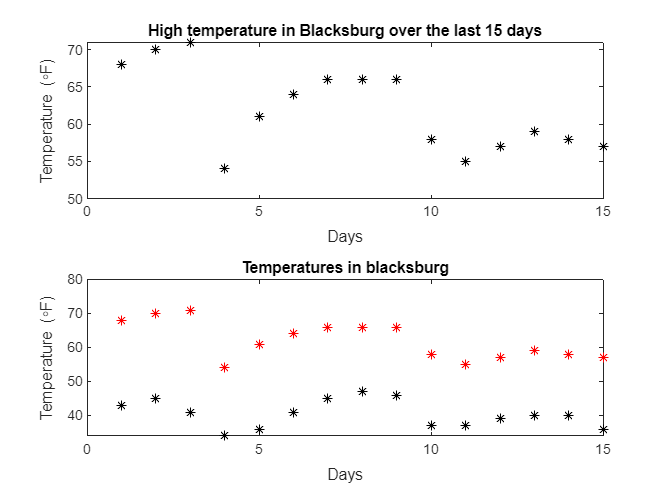

hold on
plot(days,high_temps,'*r')
plot(days,low_temps,'*k')
xlabel("Days")
ylabel('Temperature (\circF)')
title('Temperatures in blacksburg')
legeend('High Temps', 'Low Temps')
hold off

## Example 3: Line of Best Fit

Practice with the *polyfit* function

figure % Opens a new figure for this practice plot to go on

% practice code goes here
coeffs = polyfit(days,high_temps,1);

% organize and display my coefifcients of my linear equation
m = coeffs(1);
b = coeffs(2);
fprintf('The slope of my line is %.2f and the y-intercept is %.2f',m,b)

The slope of my line is -0.81 and the y-intercept is 68.49


% calculate temps for the days based on the line of best fit equation
estimated_high_temps = m*days + b

estimated_high_temps =    67.6750   66.8643   66.0536   65.2429   64.4321   63.6214   62.8107   62.0000   61.1893   60.3786   59.5679   58.7571   57.9464   57.1357   56.3250


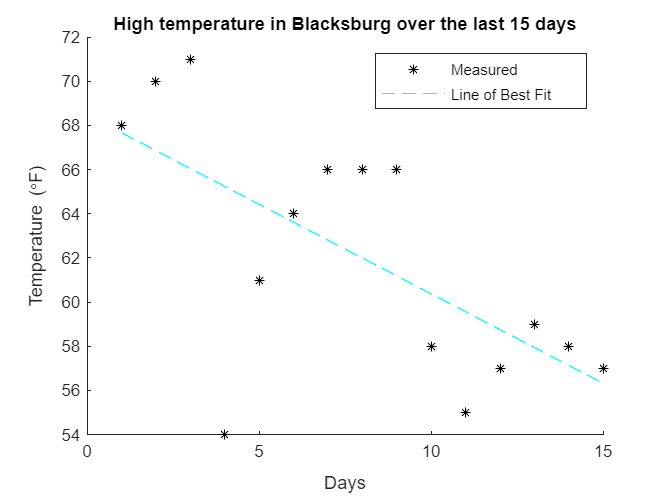


% plot the actual high temps compared to the line of best fit
% for high temps
figure
hold on
plot(days, high_temps, 'k*')
plot(days, estimated_high_temps, 'c--')
xlabel('Days')
ylabel('Temperature (\circF)')
title('High temperature in Blacksburg over the last 15 days')
legend('Measured', 'Line of Best Fit')
hold off

## Example 4: Practicing Other Data Visualization Functions

Practice with the *bar()* function

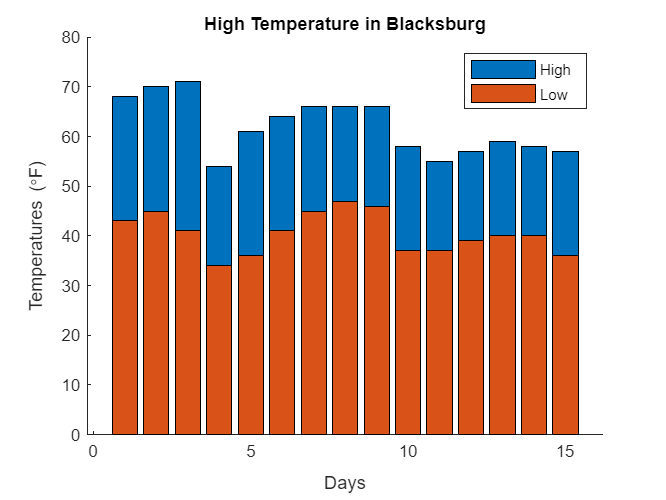

% Data
days = [1:1:15];
high_temps = [68 70 71 54 61 64 66 66 66 58 55 57 59 58 57];

figure % Opens a new figure for this practice plot to go on

hold on
% practice code goes here
bar(days,high_temps)
bar(days,low_temps)
title('High Temperature in Blacksburg')
xlabel('Days')
ylabel('Temperatures (\circF)')
legend('High','Low')
hold off

Practice with the *histogram()* function

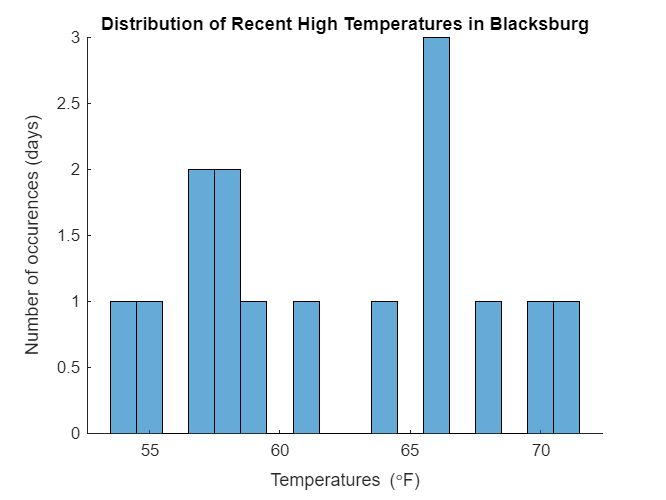

% Data
days = [1:1:15];
high_temps = [68 70 71 54 61 64 66 66 66 58 55 57 59 58 57];

figure % Opens a new figure for this practice plot to go on

% practice code goes here
hold on
histogram(high_temps)
title('Distribution of Recent High Temperatures in Blacksburg')
xlabel('Temperatures (\circF)')
ylabel("Number of occurences (days)")

Practice with the *pie()* function

% Data
Individual_Prof = 15

Individual_Prof = 15

Individual_KS = 40

Individual_KS = 40

Team_Project = 45

Team_Project = 45

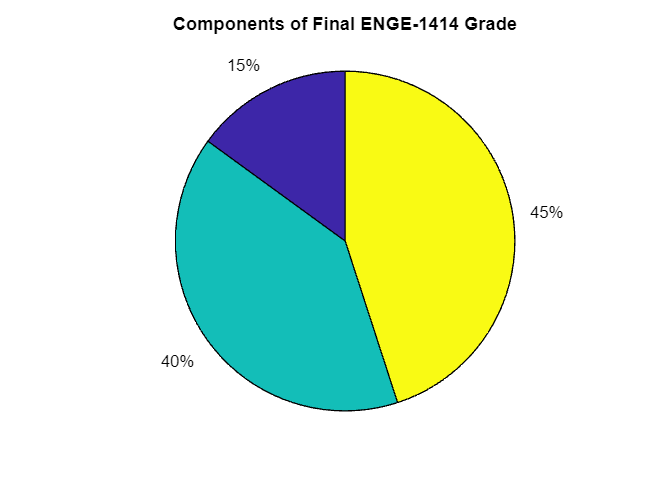


figure % Opens a new figure for this practice plot to go on

% practice code goes here
pie([Individual_Prof,Individual_KS,Team_Project])
title('Components of Final ENGE-1414 Grade ')